# TP2 de Traitement Numérique du Signal

# SCIENCES DU NUMERIQUE 1A

# Fevrier 2025 

# Aurélien VERBEKE (Groupe G)

## 2 - Génération des signaux

#### Q1

N = 100

N = 100

Fe = 10000; %Hz
Te = 1/Fe;

temps = [0:N-1]*Te;

cos_1000 = cos(2*pi*temps*1000);
cos_3000 = cos(2*pi*temps*3000);

cos_somme = cos_1000 + cos_3000;

#### Q2

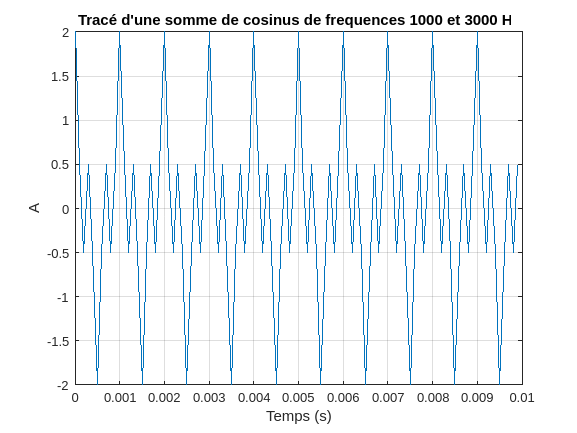

figure
plot(temps, cos_somme);
grid
xlabel('Temps (s)')
ylabel('A')
title('Tracé d''une somme de cosinus de frequences 1000 et 3000 Hz')

#### Q3

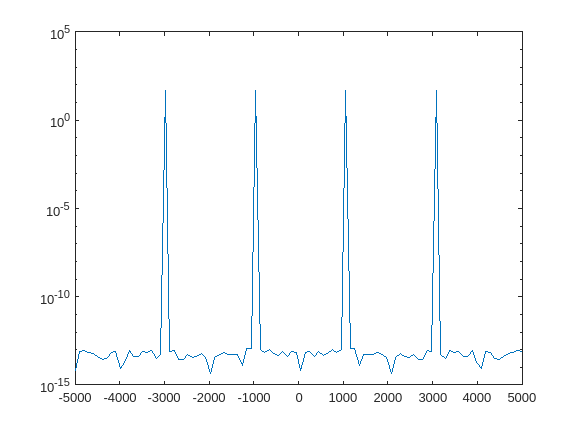

TF = fftshift(abs(fft(cos_somme)));
figure
semilogy(linspace(-Fe/2, Fe/2, N), TF);

On retrouve bien les deux cosinus de fréquence 1000 et 3000 Hz.

## 3 - Filtre passe-bas

#### Q1

On pourrait utiliser une porte de largeur 4000Hz.

#### Q2

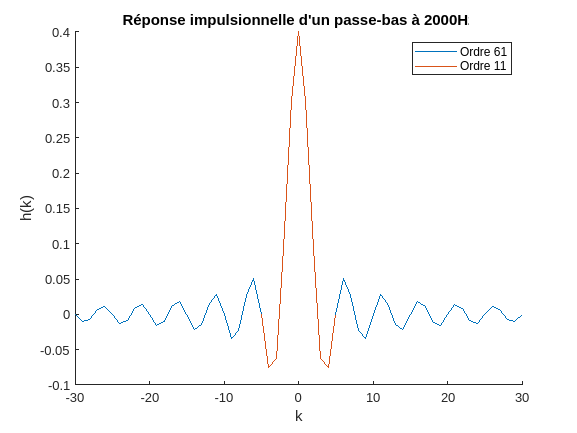

fc = 2000;
fc_tilde = fc / Fe;

filtre_11 = 2*fc_tilde*sinc(2*fc_tilde*[-5:5]);
filtre_61 = 2*fc_tilde*sinc(2*fc_tilde*[-30:30]);

figure
hold on
plot([-30:30], filtre_61);
plot([-5:5], filtre_11);
xlabel('k')
ylabel('h(k)')
title('Réponse impulsionnelle d''un passe-bas à 2000Hz')
legend("Ordre 61", "Ordre 11")

On réduit la définition de la porte.

#### Q3

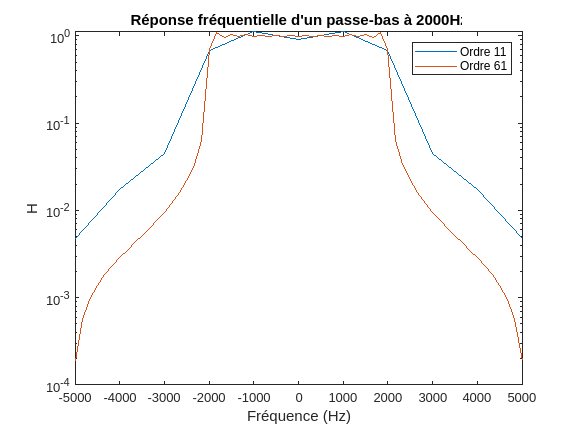

TF_filtre_11 = fftshift(abs(fft(filtre_11)));
TF_filtre_61 = fftshift(abs(fft(filtre_61)));

figure
semilogy(linspace(-Fe/2, Fe/2, 11), TF_filtre_11)
hold on
semilogy(linspace(-Fe/2, Fe/2, 61), TF_filtre_61)
xlabel('Fréquence (Hz)')
ylabel('H')
title('Réponse fréquentielle d''un passe-bas à 2000Hz')
legend("Ordre 11", "Ordre 61")

Avec plus de points sur la réponse impultionnelle, on rapproche la réponse fréquentielle de la théorie (une porte).

## 4 - Filtrage

#### Q1

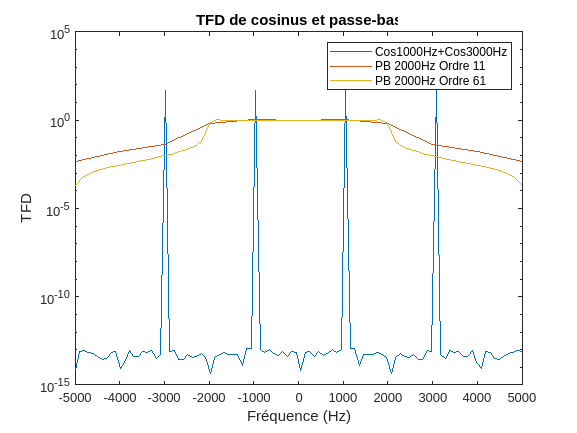

figure
semilogy(linspace(-Fe/2, Fe/2, N), TF);
hold on 
semilogy(linspace(-Fe/2, Fe/2, 11), TF_filtre_11)
semilogy(linspace(-Fe/2, Fe/2, 61), TF_filtre_61)
xlabel('Fréquence (Hz)')
ylabel('TFD')
title('TFD de cosinus et passe-bas')
legend("Cos1000Hz+Cos3000Hz", "PB 2000Hz Ordre 11", "PB 2000Hz Ordre 61")

Les filtres synthétisés semblent permettre un filtrage du cosinus de 1000Hz.

#### Q2

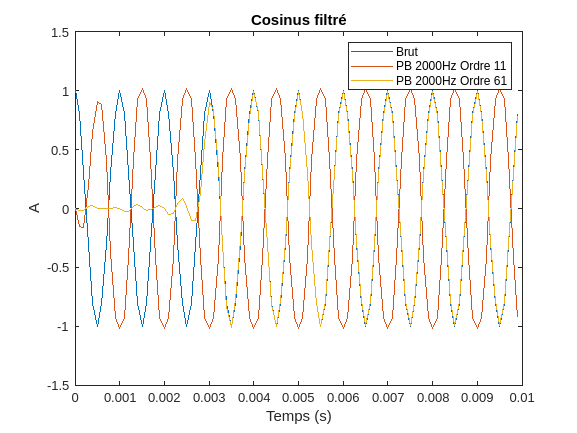

cos_filtre_11 = filter(filtre_11, 1, cos_somme);
cos_filtre_61 = filter(filtre_61, 1, cos_somme);

figure
plot(temps, cos_1000);
hold on
plot(temps, cos_filtre_11);
plot(temps, cos_filtre_61)
xlabel('Temps (s)')
ylabel('A')
title('Cosinus filtré')
legend("Brut", "PB 2000Hz Ordre 11", "PB 2000Hz Ordre 61")

On a effectivement réussi à couper la composante de 3000Hz.

Le retard constaté vient de la réponse impulsionnelle plus détaillée du filtre d'ordre 61. Pour le rendre causal, il faut le décaler de plus d'échantillons. On décale ainsi le filtre d'ordre 11 de 5 échantillons (0.0005s) et celui d'ordre 61 de 30 échantillons (0.003s).